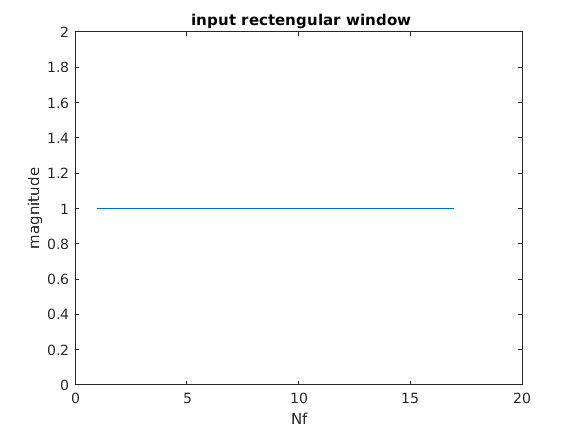

clc;
close all;
clear all;
% as per the assignment we have to take N=16 to make the filter
N=16;
fp=200;%pass band frequency
fs=600;%stop band frequency 
f=1000;%sampling frequency 

wp=2*(fp/f);
ws=2*(fs/f);

window_1=boxcar(N+1);% rectengular window
window_2=bartlett(N+1);% traingular window
window_3=hanning(N+1);% raised cosine window
window_4=kaiser(N+1);%kaiser window

plot(window_1);
xlabel('Nf');
ylabel('magnitude');
title(' input rectengular window')

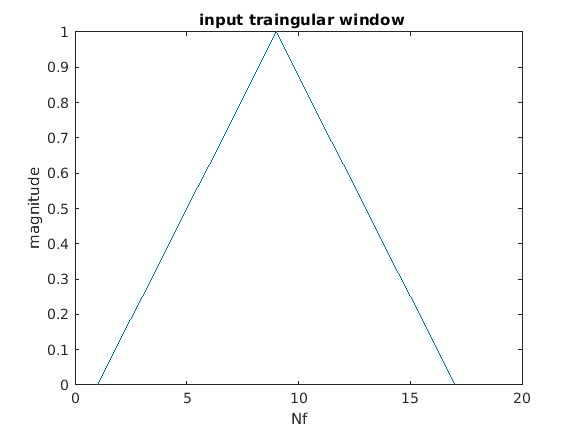

plot(window_2);
xlabel('Nf');
ylabel('magnitude');
title(' input traingular window');

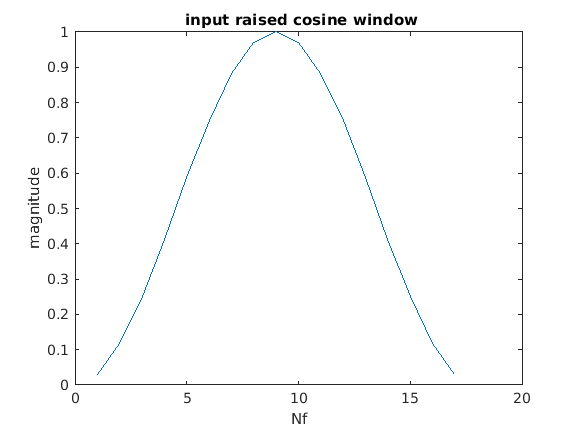

plot(window_3);
xlabel('Nf');
ylabel('magnitude');
title(' input raised cosine window');

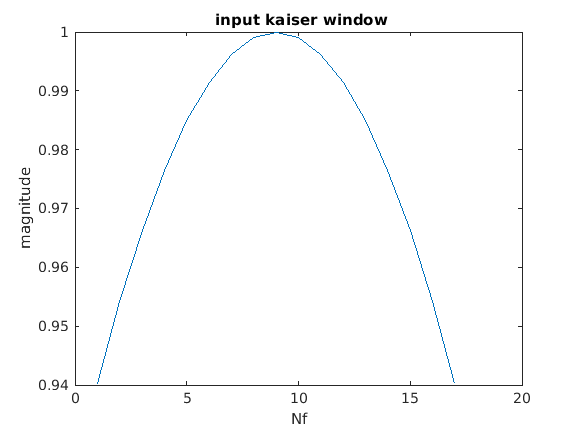

plot(window_4);
xlabel('Nf');
ylabel('magnitude');
title(' input kaiser window')

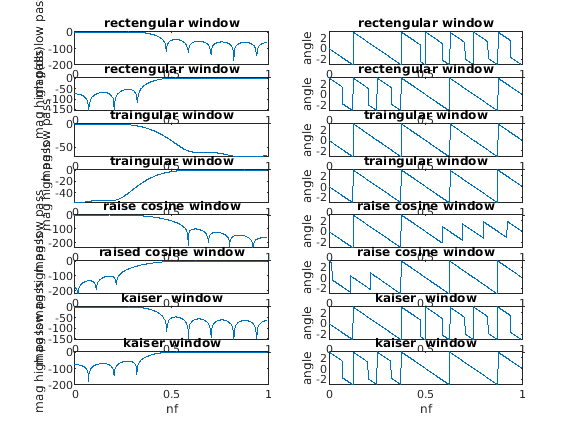


%wn=[wp,ws]
wn=2*(fp/f);
a=fir1(N,wn,window_1);
ah=fir1(N,wn,'high',window_1);
b=fir1(N,wn,window_2);
bh=fir1(N,wn,'high',window_2);
c=fir1(N,wn,window_3);
ch=fir1(N,wn,'high',window_3);
d=fir1(N,wn,window_4);
dh=fir1(N,wn,'high',window_4);
%fir filter using rectengular window
[E,w]=freqz(a,1);
[Eh,w1]=freqz(ah,1);
subplot(8,2,1);
plot(w/pi,20*log(abs(E)));
xlabel('nf');
ylabel(' mag(db)low pass');
title('rectengular window');
subplot(8,2,2)
plot(w/pi,angle(E));
xlabel('nf');
ylabel('angle');
title('rectengular window');
subplot(8,2,3);
plot(w1/pi,20*log(abs(Eh)));
xlabel('nf');
ylabel('mag high pass');
title('rectengular window');
subplot(8,2,4)
plot(w1/pi,angle(Eh));
xlabel('nf');
ylabel('angle');
title('rectengular window');

%fir filter using traingular window
[G,w2]=freqz(b,1);
[Gh,w3]=freqz(bh,1);

subplot(8,2,5);
plot(w2/pi,20*log(abs(G)));
xlabel('nf');
ylabel('mag low pass');
title('traingular window');
subplot(8,2,6)
plot(w2/pi,angle(G));
xlabel('nf');
ylabel('angle');
title('traingular window');
subplot(8,2,7);
plot(w3/pi,20*log(abs(Gh)));
xlabel('nf');
ylabel('mag high pass');
title('traingular window');
subplot(8,2,8)
plot(w3/pi,angle(Gh));
xlabel('nf');
ylabel('angle');
title('traingular window');
%fir filter using raised cosine  window
[H,w4]=freqz(c,1);
[Hh,w5]=freqz(ch,1);

subplot(8,2,9);
plot(w4/pi,20*log(abs(H)));
xlabel('nf');
ylabel('mag low pass');
title('raise cosine window');
subplot(8,2,10)
plot(w4/pi,angle(H));
xlabel('nf');
ylabel('angle');
title('raise cosine window');
subplot(8,2,11);
plot(w5/pi,20*log(abs(Hh)));
xlabel('nf');
ylabel('mag high pass');
title('raised cosine window');
subplot(8,2,12)
plot(w5/pi,angle(Hh));
xlabel('nf');
ylabel('angle');
title('raise cosine window');

%fir filter using kaiser  window
[I,w6]=freqz(d,1);
[Ih,w7]=freqz(dh,1);

subplot(8,2,13);
plot(w6/pi,20*log(abs(I)));
xlabel('nf');
ylabel('mag low pass');
title('kaiser  window');
subplot(8,2,14)
plot(w6/pi,angle(I));
xlabel('nf');
ylabel('angle');
title('kaiser  window');
subplot(8,2,15);
plot(w7/pi,20*log(abs(Ih)));
xlabel('nf');
ylabel('mag high pass');
title('kaiser window');
subplot(8,2,16)
plot(w7/pi,angle(Ih));
xlabel('nf');
ylabel('angle');
title('kaiser  window');